# TIME

rng('shuffle')
format long

X=[];
Y=[];
for k=1:100
    n=k*10^3;
    f1=@() sort(rand(1,n));
    t=timeit(f1);
    X=[X;n];
    Y=[Y;t];
end
X=X/10^6

X =    0.001000000000000
   0.002000000000000
   0.003000000000000
   0.004000000000000
   0.005000000000000
   0.006000000000000
   0.007000000000000
   0.008000000000000
   0.009000000000000
   0.010000000000000


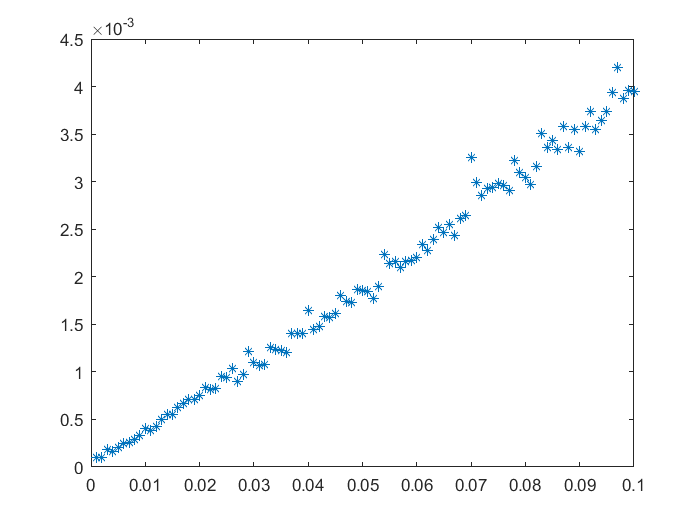

plot(X,Y,'*')

disp("Variant A")

Variant A


A=[ones(k,1),X];
%c=(A'*A)\A'*Y
c=A\Y %https://www.mathworks.com/help/symbolic/mldivide.html

c =   -0.000070800946970
   0.040046649486199


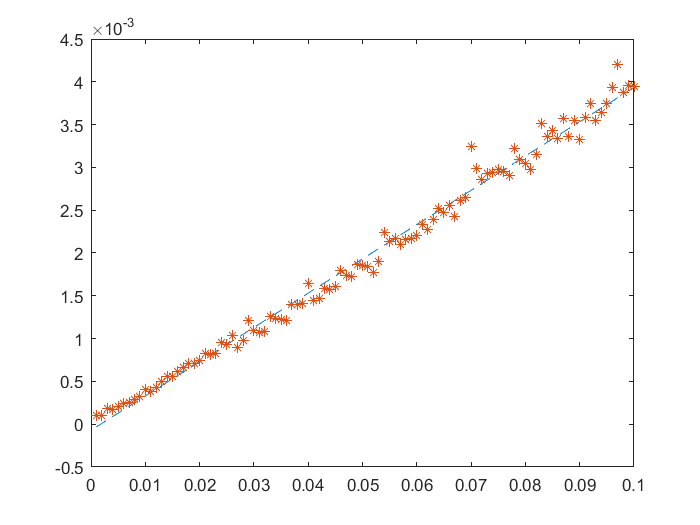

YY=c(1)+c(2)*X;
plot(X,YY,'--',X,Y,'*')

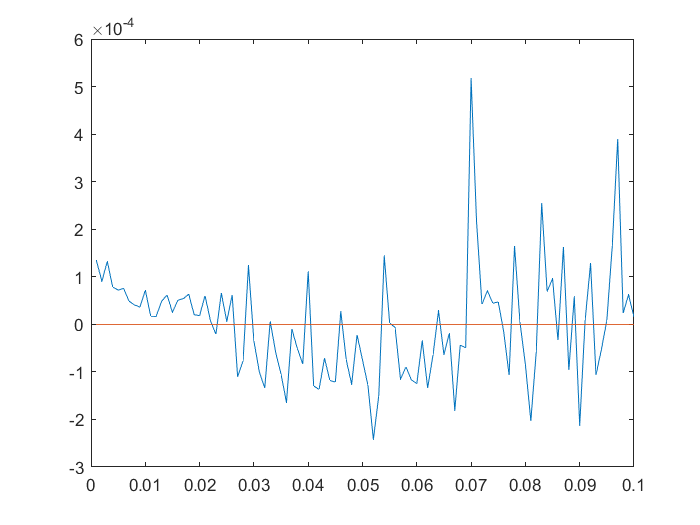

plot(X,Y-YY,X,X*0)

RSS=sum((Y-YY).^2)

RSS =      1.353255604902994e-06


disp("Variant B")

Variant B


A=[ones(k,1),X,X.^2];
c=A\Y %https://www.mathworks.com/help/symbolic/mldivide.html

c = 	1.0e+-4 *

   0.328403387792719
   0.000194193507938
   0.000000000380273


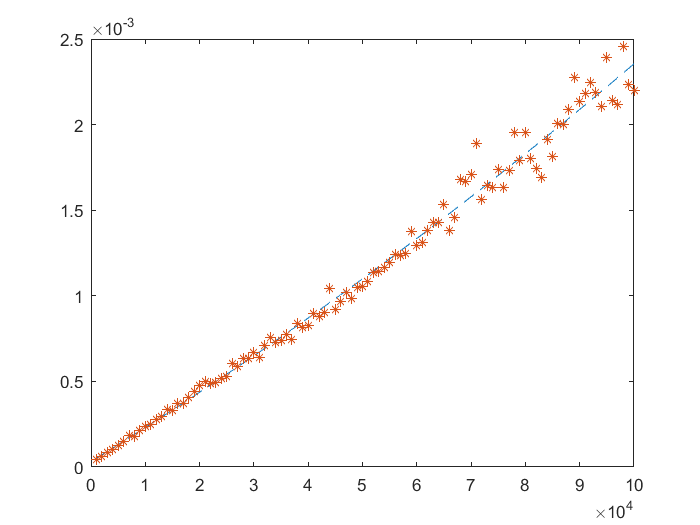

YY=c(1)+c(2)*X+c(3)*X.^2;
plot(X,YY,'--',X,Y,'*')

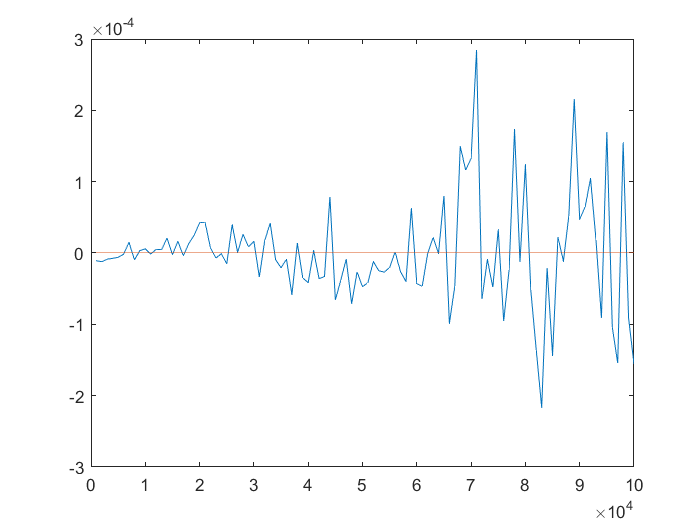

plot(X,Y-YY,X,X*0)

RSS=sum((Y-YY).^2)

RSS =      5.563198069051196e-07


disp("Variant C")

Variant C


A=[ones(k,1),X,X.*log(X)];
c=A\Y %https://www.mathworks.com/help/symbolic/mldivide.html

c = 	1.0e+-4 *

   0.687137298770749
  -0.000113787261107
   0.000029620200130


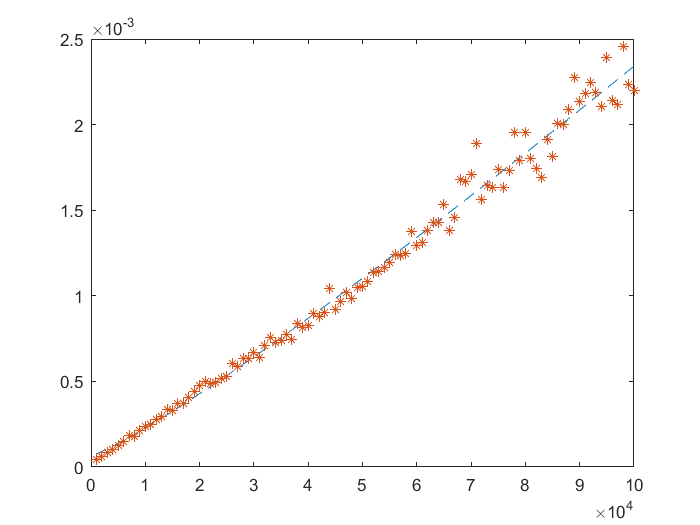

YY=c(1)+c(2)*X+c(3)*X.*log(X);
plot(X,YY,'--',X,Y,'*')

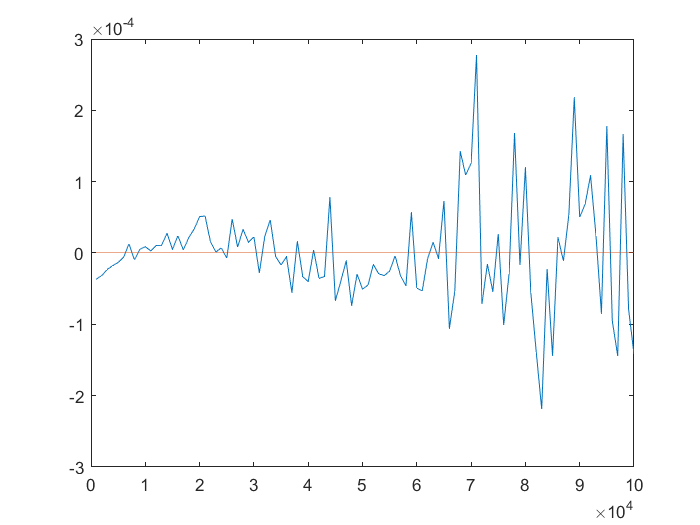

plot(X,Y-YY,X,X*0)

RSS=sum((Y-YY).^2)

RSS =      5.588534310367462e-07


disp("Variant D")

Variant D


A=[ones(k,1),X,X.^2,X.*log(X)];
c=A\Y %https://www.mathworks.com/help/symbolic/mldivide.html

c = 	1.0e+-4 *

   0.420931379595816
   0.000120358746048
   0.000000000293696
   0.000007061459743


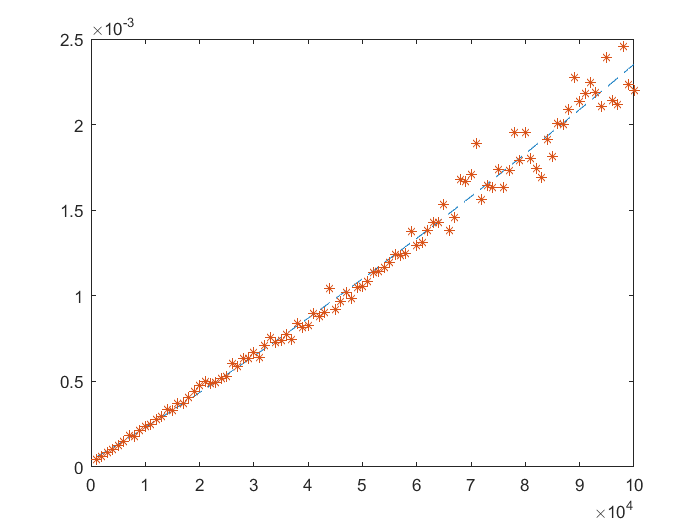

YY=c(1)+c(2)*X+c(3)*X.^2+c(4)*X.*log(X);
plot(X,YY,'--',X,Y,'*')

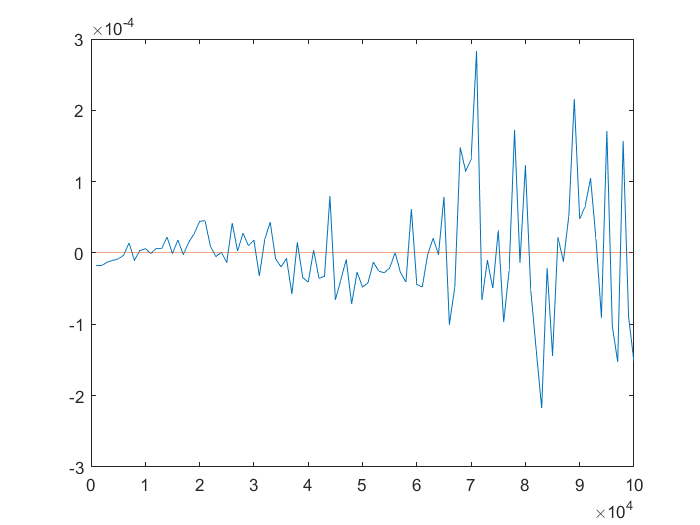

plot(X,Y-YY,X,X*0)

RSS=sum((Y-YY).^2)

RSS =      5.560622511591966e-07
